# Multilevel mediation 

### Mediation analysis: The basics

Mediation is a useful tool for connecting variables into pathways. It extends the idea of a simple association between two variables (let's call them ***x*** and ***y****)* to a pathway involving three (or more) variables.  Let's write the association ***x*** predicts ***y*** like this: **[ *****x -> y ].***  With mediation analysis, you can build a model of associations among three variables, i.e., **[ *****x *****->***** m *****->***** y *****]**. ***m*** is a mediator, a variable that explains some or all of the relationship between ***x ***and ***y***.  

Mediation models are especially useful for developing models in which an association between two variables is transmitted via a third variable. For example, the effects of a psychological stressor (x) on heart rate (y) may be mediated by activity in brain systems responsible for threat. The stressor activates the brain, and the brain in turn controls the heart.  

In mediation analysis, ***x*** is called the initial variable. it will often be an experimental variable (IV) that is experimentally manipulated, but it doesn't have to be.  ***y*** is called the outcome variable, and it is usually the endpoint that one is interested in explaining. m is the mediator, and is usually a variable that is thought to be important for transmitting the effect of ***x*** on ***y, ***or on the "causal path" from ***x ***to*** y. ***It is also possible to include multiple initial variables, multiple mediators, and other covariates in such models. The broader family that the [ *x *->* m *->* y *] model belongs to is called **path models****.**

Here are some other examples. Exercise may improve memory via neurogenesis.  Exercise causes new neurons to be generated in the brain, which helps the brain form new memories more efficiently.  here, ***x*** is exercise, ***m*** is neurogenesis, and ***y*** is memory. Smoking (***x***) may lead to premature death (***y***) via increased rates of cancer (***m***). 

**A note on causality**. Mediation models of the type we explore here (and path models more generally) are build on linear regression, with the same assumptions and limitations of other linear models. It is a directional model: As with a standard multiple regression model, we are explaining ***y*** as a function of ***x*** and ***m***. And, as with standard regression, the presence of a statistical association does not provide direct information on causality. The observed relationships could, in principle, be caused by other variables that are not included in the model (i.e., lurking variables or common causes), and/or the direction of causality can be reversed from how you've formulated it in the model.  Experimental manipulation of variables can provide stronger evidence for causal associations, and sometimes both ***x*** and ***m*** are experimentally manipulated. However, when variables are observed rather than manipulated, statistical associations very rarely provide strong information about causality. 

### Brain mediators

In neuroimaging studies, we often manipulate brain activity experimentally with tasks, and measure both brain activity (e.g., with fMRI) and behavior (e.g., performance or reported experiences). 

The mediation framework we'll explore here looks like this:

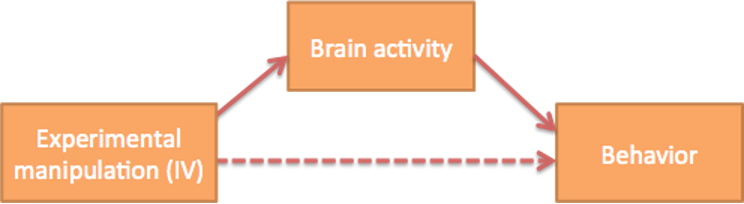		

		    X                                                M                                                   Y

X represents the task condition -- e.g., in our example here, the temperature of a hot stimulus applied to the skin. It is often coded with 1 or -1 ("effects coding") when there are two conditions, but can be coded with linear contrast codes or other numerical values when there are more than two conditions. M represents fMRI activity.  Y represents a behavioral outcome of interest.

In the standard mediation model, each of X, M, and Y are vectors with one observation per person. Thus, the individual participant is the unit of observation. When this is the case, we'll call this a **single-level** mediation. 99% or so of the mediation analyses in the literature are single-level models.  For example, X can include a vector of individuals who are either smokers (coded as 1) or non-smokers (coded as -1), and we include measures of both the incidence of cancer (M) and survival time (Y) for each person.

Here, for our neuroimaging analysis, we'll extend this in two ways:

- We'll search over brain voxels, testing each voxel in an fMRI study as a mediator one at a time. We'll then save maps of how strong the mediation effect is.

- We'll change the unit of observation from the participant to conditions within-participant.  This is possible because in fMRI, we typically we vary X within-person by including different experimental tasks that might impact M and Y. We can also observe fMRI acitivity (M) and behavior (Y) as they vary within-person.  When we model these within-person relationships and perform statistical tests to generalize the associations to a population of individuals, we are performing multilevel mediation.   				

The [Multilevel Mediation and Moderation (M3) Matlab Toolbox](https://github.com/canlab/MediationToolbox) will perform both single- and multilevel mediation. The function **mediation.m** can operate on any type of input data (behavior, psychosocial measures, physiology, brain, genetics, etc.), and will run both single and multilevel mediation depending on the input data.

The toolbox also has special functions for running mediation on each voxel in a neuroimaging dataset (single or multilevel) and saving maps of mediation effects:

### Load the dataset

Locally or from the web					

fmri_data_file = which('bmrk3_6levels_pain_dataset.mat');
fmri_data_file

if isempty(fmri_data_file)

    % attempt to download
    disp('Did not find data locally...downloading data file from figshare.com')

    fmri_data_file = websave('bmrk3_6levels_pain_dataset.mat', 'https://ndownloader.figshare.com/files/12708989');

end

load(fmri_data_file);

### Prepare metadata

subject_id = mat2cell(image_obj.additional_info.subject_id, 6*ones(1, 33))' ;

ratings = mat2cell(image_obj.Y, 6*ones(1, 33))';

temperatures = mat2cell(image_obj.additional_info.temperatures, 6*ones(1, 33))';

### Prepare brain data

Write one 4-D Nifti image (.nii) to disk for each subject. The .nii image has one 3-D brain volume per temperature for 6 temperatures total per subject.

N = length(subject_id)
for i = 1:N
tmp_obj = get_wh_image(image_obj, image_obj.additional_info.subject_id == i);
tmp_obj.fullpath = fullfile(pwd, sprintf('bmrk3_6levels_subject%3.0f.nii', i));
M{1, i} = tmp_obj.fullpath;
write(tmp_obj);
end

ls

### Set up and run multilevel mediation

- Create a mediation directory to save output, and go there

- Configure setup options in a SETUP structure

- Run mediation (this will save files to disk)

*Note*: The mask will likely have to be resliced (resampled and interpolated) to match the origin and dimensions of the brain dataset.

mkdir mediation_results
cd mediation_results

SETUP.mask = which('gray_matter_mask.nii');
SETUP.preprocX = 0;
SETUP.preprocY = 0;
SETUP.preprocM = 0;

mediation_brain_multilevel(temperatures, ratings, M, SETUP);

# NOTE: Work in progress! 

May add the images as an example dataset

cd ..

single_trial_image_names = M;

save bmrk3_6levels_metadata subject_id ratings temperatures single_trial_image_names